# Control experiments

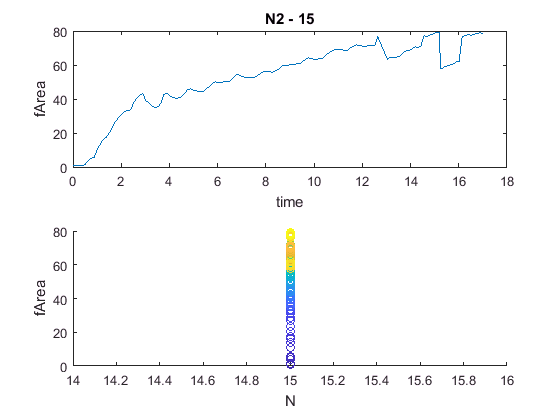

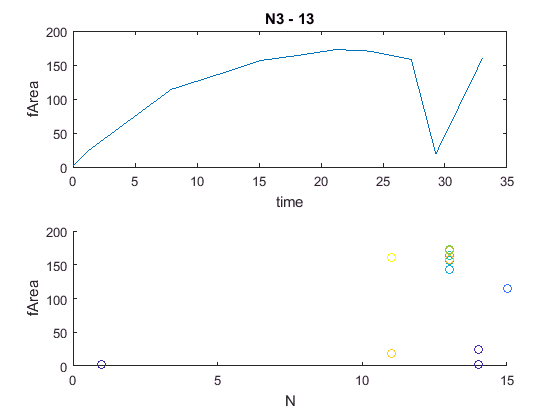

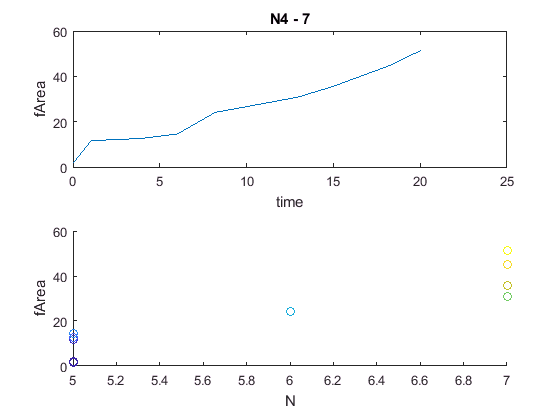

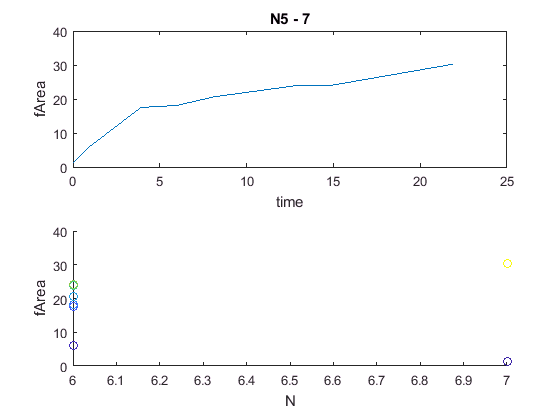

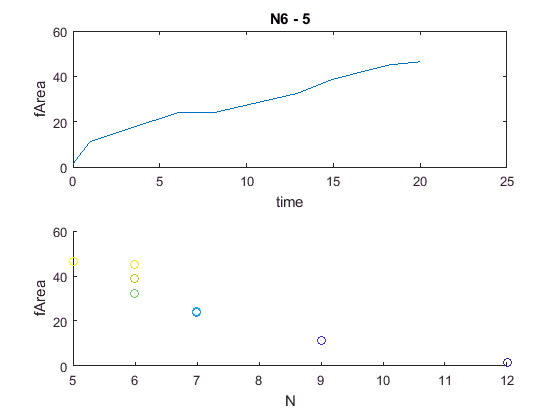

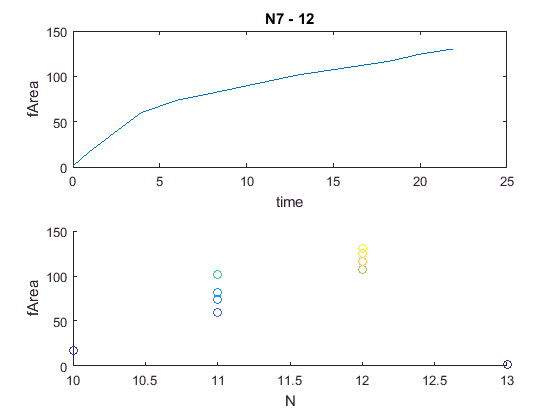

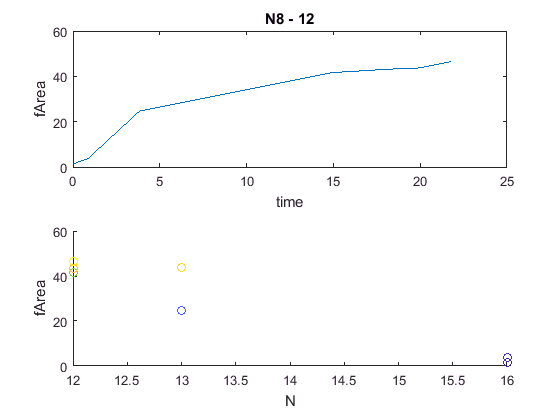

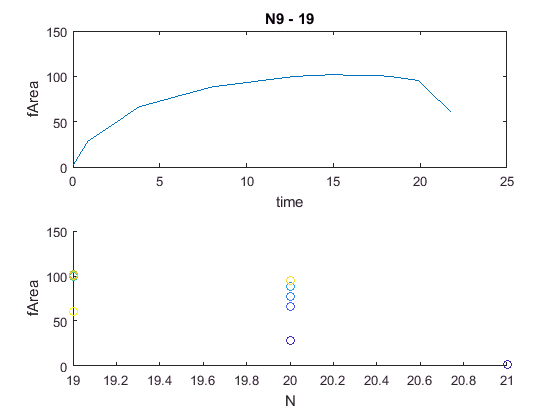

ControlT = table((2:10)');
ControlT.Properties.VariableNames = {'tag'};
for k=1:9
    tag = ['N',num2str(k+1)];
    %ControlT.tag(k) = k;
    load(['Data\',tag,'_Data.mat'],'A')
    [M,I] = max(A.fArea);
    ControlT.MaxArea(k) = M;
    ControlT.MaxDay(k) = floor(A.runtime(I));
    ControlT.halfTime(k) = A.runtime(find(A.fArea>=M./2,1));
    ControlT.halfTime2(k) = A.runtime(find(A.fArea>=0.9.*M,1));
    ControlT.Pop_i(k) = A.Pop(2);
    try
        ControlT.Pop_Amax(k) = A.SmoothPop(I);
    catch
        ControlT.Pop_Amax(k) = A.Pop(I);
    end
    % dig rate
    gradA = diff(A.fArea)./diff(A.runtime);
    ControlT.MaxRate(k) = max(gradA);
    
    %plot
    figure
    subplot(2,1,1)
    plot(A.runtime,A.fArea)
    title([tag,' - ',num2str(ControlT.Pop_Amax(k))])
    xlabel('time')
    ylabel('fArea')
    subplot(2,1,2)
    scatter(A.SmoothPop,A.fArea,[],A.runtime)
    xlabel('N')
    ylabel('fArea')
end

## Analysis

disp(ControlT)

    tag    MaxArea    MaxDay    halfTime    halfTime2    Pop_i    Pop_Amax    MaxRate
    ___    _______    ______    ________    _________    _____    ________    _______
     2     79.199     15        2.6387      11.764       15       15          115.71 
     3     172.75     21        7.9218      15.179       14       13          37.395 
     4      51.54     20        12.954      20.065        5        7          9.5188 
     5     30.245     21        3.9061      21.898        6        7          4.8614 
     6     46.452     20        5.9766      18.225       12        5          9.9849 
     7     130.12     21        5.9621      19.995       13       12           16.52 
     8     46.547     21        3.8229  

HalfTimeMean = mean(ControlT.halfTime([1 3:end]))

HalfTimeMean = 5.6115

HalfTimeSD = std(ControlT.halfTime([1 3:end]))

HalfTimeSD = 3.2174

** get very similar response time (half time) ~5.6+/-3.2

HalfTime2Mean = mean(ControlT.halfTime2([1 3:end]))

HalfTime2Mean = 17.2168

HalfTime2SD = std(ControlT.halfTime2([1 3:end]))

HalfTime2SD = 3.6754


lm1 = fitlm(ControlT,'MaxArea ~ Pop_Amax')

lm1 = Linear regression model:
    MaxArea ~ 1 + Pop_Amax

Estimated Coefficients:
                   Estimate      SE       tStat     pValue 
                   ________    ______    _______    _______
    (Intercept)    19.032      38.977    0.48828    0.64028
    Pop_Amax       5.5742      3.0655     1.8184    0.11184

Number of observations: 9, Error degrees of freedom: 7
Root Mean Squared Error: 41.5
R-squared: 0.321,  Adjusted R-Squared 0.224
F-statistic vs. constant model: 3.31, p-value = 0.112

plot(lm1)

lm2 = fitlm(ControlT,'MaxRate ~ Pop_Amax')

lm2 = Linear regression model:
    MaxRate ~ 1 + Pop_Amax

Estimated Coefficients:
                   Estimate      SE       tStat      pValue 
                   ________    ______    ________    _______
    (Intercept)    -8.941      31.871    -0.28053    0.78718
    Pop_Amax        3.054      2.5066      1.2184    0.26255

Number of observations: 9, Error degrees of freedom: 7
Root Mean Squared Error: 33.9
R-squared: 0.175,  Adjusted R-Squared 0.0571
F-statistic vs. constant model: 1.48, p-value = 0.263

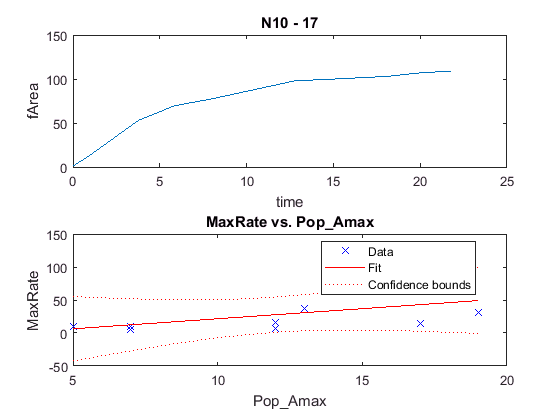

plot(lm2)


% calc Max rate per ant
ControlT.MaxRatePerAnt = ControlT.MaxRate./ControlT.Pop_Amax;
mean(ControlT.MaxRatePerAnt(2:end))

ans = 1.4204

std(ControlT.MaxRatePerAnt(2:end))

ans = 0.7623

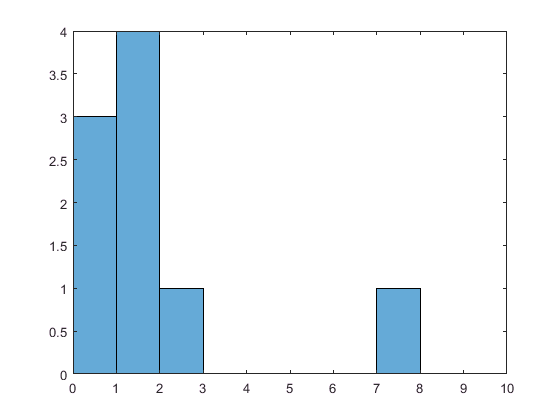

figure
histogram(ControlT.MaxRate./ControlT.Pop_Amax,0:1:10)

max(ControlT.MaxRate./ControlT.Pop_Amax)

ans = 7.7139

from linear fits analysis get parameters like Rasse and Deneuberg (2001):

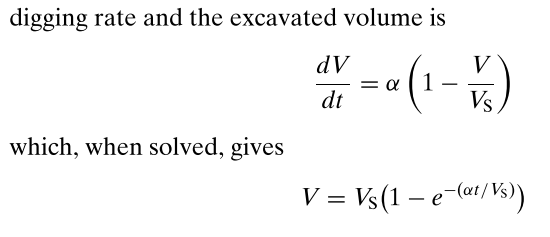

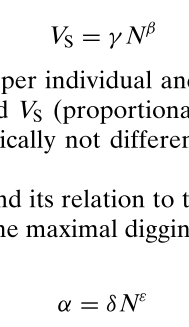

As = gN; g = 5.574

a = dN; d = 3.054

using their model try to predict A growth

Afunc = @(N,d,g,t) g.*N.*(1-exp(-d.*t./g));


check on N10 w/ N=17

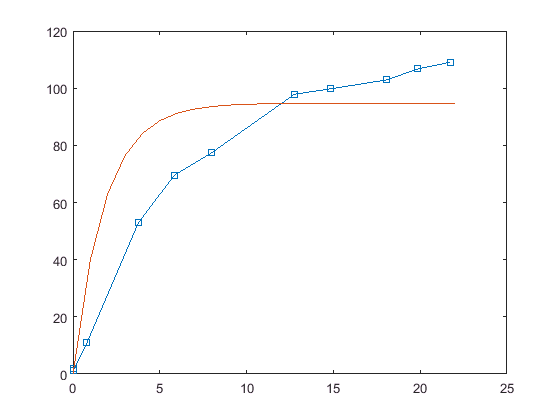

t=0:1:22;
Am = Afunc(17,3.054,5.574,t);

figure; plot(A.runtime,A.fArea,'-s',t,Am)

plotting all on same plot

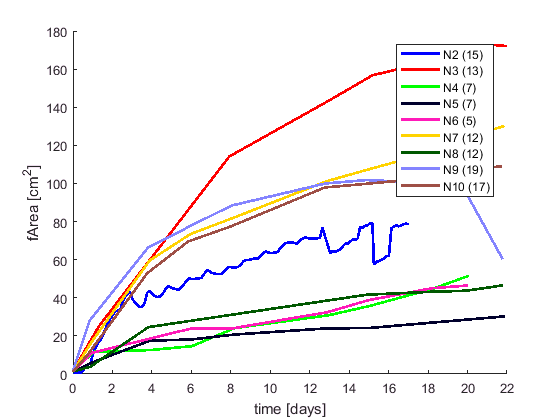

figure
mikra = {};
clearvars tag
colors = distinguishable_colors(9);
for k=1:9
    tag{k} = ['N',num2str(k+1)];
    %ControlT.tag(k) = k;
    load(['Data\',tag{k},'_Data.mat'],'A')
        %plot
        hold on 
        plot(A.runtime,A.fArea,'Color',colors(k,:),'LineWidth',2)
    xlabel('time [days]')
    ylabel('fArea [cm^2]')
    mikra(k) = {[tag{k},' (',num2str(ControlT.Pop_Amax(k)),')']};
end
xlim([0 22])
legend(mikra')

save('Data\ControlExp.mat','ControlT')